% Load the crack data filt and create the Risk variable
load CrackData.mat
cutoffArea = 4000;
crackData.Risk = discretize(crackData.Area,[0,cutoffArea,inf], ...
    "categorical",["Mild","Severe"]);

The goal here is to analyze the concrete crack image data using the `crackData` table, which is provided in the file `CrackData.mat`.

In each concrete crack image, a single pixel has the dimensions of **0.5 mm **by** 0.5 mm**.

crackData.MaxWidth = crackData.MaxWidth * 0.5;

crackData = 200×5 table
    NumRegions    Area    MaxWidth     fileName      Risk
    __________    ____    ________    ___________    ____

        2         2461     8.9443     "00001.jpg"    Mild
        2         2125     8.9443     "00002.jpg"    Mild
        2         2417          8     "00003.jpg"    Mild
        1         2438     7.0711     "00004.jpg"    Mild
        4         1479     9.2195     "00005.jpg"    Mild
        1         2356          7     "00006.jpg"    Mild
        1         2926     9.4868     "00007.jpg"    Mild
        1         2573     7.6158     "00008.jpg"    Mild
        2         1861     7.0711     "00009.jpg"    Mild
        2         2663      8.544     "00010.jpg"    Mild
        1         3149     11.705     "00011.jpg"    Mild
        1         2722     9.4868     "00012.jpg"  

crackData.Area = crackData.Area * 0.5^2 ; 

mildMeanWidth = mean(crackData.MaxWidth(crackData.Risk == "Mild")) ; 
severeMeanWidth = mean(crackData.MaxWidth(crackData.Risk == "Severe")) ; 


severeMedianWidth = median(crackData.MaxWidth(crackData.Risk == "Severe")) 

severeMedianWidth = single
17.4642

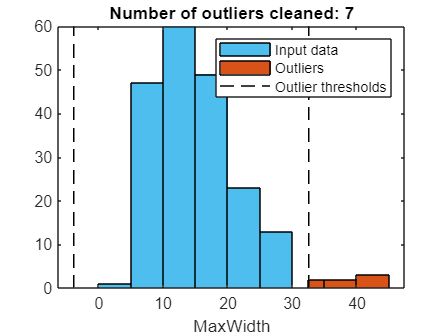

% Remove outliers
[newTable,outlierIndices,~,thresholdLow,thresholdHigh] = rmoutliers(crackData,...
    "DataVariables","MaxWidth");

% Display results
figure
[~,binEdges] = histcounts(crackData.MaxWidth);
binEdges = unique([binEdges thresholdLow.MaxWidth thresholdHigh.MaxWidth]);
binEdges = binEdges(isfinite(binEdges));
histogram(crackData.MaxWidth,"BinEdges",binEdges,"FaceColor",[77 190 238]/255,...
    "FaceAlpha",1,"DisplayName","Input data")
hold on

% Plot outliers
histogram(crackData.MaxWidth(outlierIndices),"BinEdges",binEdges,...
    "FaceColor",[217 83 25]/255,"FaceAlpha",1,"DisplayName","Outliers")

% Plot outlier thresholds
plot([thresholdLow.MaxWidth*[1 1] NaN thresholdHigh.MaxWidth*[1 1]],...
    [ylim missing ylim],"k--","DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices))
legend
xlabel("MaxWidth")

clear thresholdLow thresholdHigh binEdges

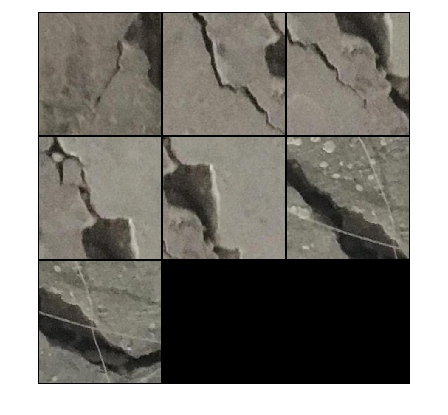

outlierImages = crackData.fileName(outlierIndices);
montage(outlierImages,'BorderSize',2)

Now let's visualize the results 

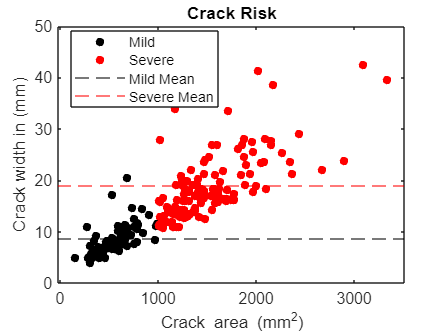

gscatter(crackData.Area,crackData.MaxWidth,crackData.Risk,"kr")
yline(mildMeanWidth,"k--","DisplayName","Mild Mean")
yline(severeMeanWidth,"r--","DisplayName","Severe Mean")
title("Crack Risk")
xlabel("Crack area (mm^2)")
ylabel("Crack width in (mm)")